# Calculate Wall Thickness Given Factor of Safety

**Author:** Evan Olsen

**Date:** 01/25/2024

**Description: **Determines the necessary wall thickness to match a given factor of safety.

clc; clear; close all;

% Import Pre-calculated Variables in ANSYS. This will be a pain to do but
% the easiest method is to output pressure from your CFD simulation, and
% export wall temperature in terms of XYZ from your Transient Thermal
% simulation on the interior reference surface. Determine which data varies
% along your contour, typically the z-axis, and then import into matlab
% using the importtable() and table2array() functions. For reusability, you
% can save() to a .mat file.
load('ANSYS_P_x.mat')
load('Temp_XYZ_Exterior.mat')
load('Temp_XYZ_Interior.mat')

% Pre-calculated from parametric-liquid-engine script located at 
% https://github.com/RIT-Launch-Initiative/parametric-liquid-engine or
% other script.
load('R_x.mat')

% Reversing ANSYS output variables to match the pre-calculated contour
% orientation. Edit this as needed, it changes depending on how your ANSYS
% geometry is set up.
Temp_XYZ_Interior(:,1)=-Temp_XYZ_Interior(:,1);
P_x(:,1)=-P_x(:,1);

% Neccessary Factor of Safety
FOS = 5.0;

## **Determining Yield Strength Table for 304 Stainless Steel**

*Table 1. Allowable Stress Chart for 300* Series Stainless Steel*

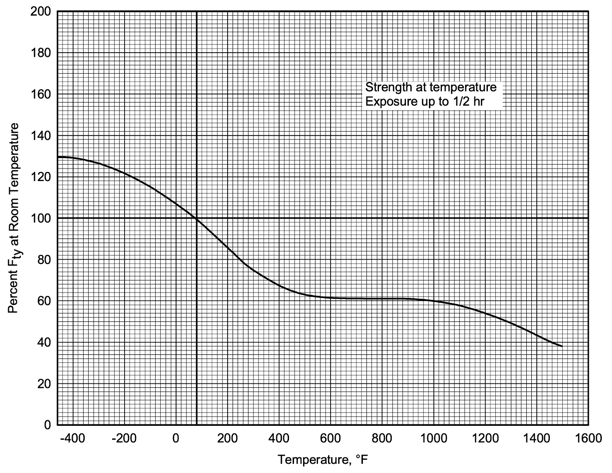

Source: [http://everyspec.com/FAA/FAA-General/DOT-FAA-AR-MMPDS-01-JAN2003_24102/,](http://everyspec.com/FAA/FAA-General/DOT-FAA-AR-MMPDS-01-JAN2003_24102/,)* Page 279*

% For 304 Stainless Steel - Yield Strength vs. Temperature
yield_strength_tbl = [215e6,210.7e6,184.9e6,159.1e6,146.2e6,135.45e6,133.3e6,131.15e6,131.15e6,131.15e6,129e6,124.7e6,116.1e6,107.5e6,92.45e6,81.7e6];
temp_tbl = [299.82,310.93,366.48,422.04,477.59,533.15,588.71,644.26,699.82,755.37,810.93,866.48,922.04,977.59,1033.15,1088.71];

## **Creating Fit Curves to Equalize the Matrix Lengths**

This section uses the cftool() curve fitting tool within MATLAB to create curve fits for the yield strength table, as well as using that function to equalize the matrix lengths. A linear curve fit is good enough for these purposes.

[fitresult_ExtTemp,~] = createFit_ExtTemp(Temp_XYZ_Exterior(:,1),Temp_XYZ_Exterior(:,2));
for i=1:length(Temp_XYZ_Interior(:,1))
    exteriorTemp(i) = feval(fitresult_ExtTemp,Temp_XYZ_Exterior(i,1));
end

[fitresult_yield,~] = createFit_stress(temp_tbl,yield_strength_tbl);

% Evaluates the curve fit to determine the yield strength on the interior
% wall in terms of the engine length.
for i=1:length(Temp_XYZ_Interior(:,2))
    yield_strength_in(i) = feval(fitresult_yield,Temp_XYZ_Interior(i,2)); % [Pa]
end
for i=1:length(Temp_XYZ_Interior(:,2))
    yield_strength_out(i) = feval(fitresult_yield,exteriorTemp(i)); % [Pa]
end

% Calculates the average yield strength between the outside and inside
% surfaces of the engine, to compensate for the fact that there is a
% temperature gradient from the inside surface to the outside. This method
% gives the most conservative answer compared to averaging the inner and
% outer wall temperatures, due to the increased change in yield strength
% per unit temperature.
yield_strength_avg = (yield_strength_in + yield_strength_out)./2; % [Pa]

% Creates a linear curve fit for the input pressure curve in order to
% equalize the lengths of the matrices with the inputted x-data within the
% wall temperature matrix.
[fitresult_pressure,~] = createFit_Pressure(P_x(:,1),P_x(:,2));
for j=1:length(Temp_XYZ_Interior(:,1))
    internal_pressure(j) = feval(fitresult_pressure,Temp_XYZ_Interior(j,1)); % [Pa]
end

% Creates a linear curve fit for the wall y-data to match the x-data in the
% wall temperature matrix.
[fitresult_wall,~] = createFit_wall(R_x(1,:),R_x(2,:));
for k=1:length(Temp_XYZ_Interior(:,1))
    local_radius(k) = feval(fitresult_wall,Temp_XYZ_Interior(k,1)); % [m]
end

## **Calculating Minimum Wall Thickness in Terms of X**

The following equation was given to determine the wall thickness for a certain yield strength (S) on the wall. To incorporate our factor of safety, the yield strength is divided by the FOS. This is equivalent to multiplying the wall thickness by the FOS. 

*Figure 1. Wall Thickness Equation for FOS 1.0*

Source: [*http://www.cientificosaficionados.com/libros/cohetes.pdf*](http://www.cientificosaficionados.com/libros/cohetes.pdf)

% We will define a base thickness for the contour to provide simple
% structure. This is important towards the end of the nozzle due to the
% required wall thickness being << than the required thickness in the
% combustion chamber.
base_thickness = 0; % [m]

% Utilizes above defined equation in Figure 1. to determine the minimum
% wall thickness to meet the given factor of safety.
min_t_wall = (internal_pressure .* local_radius .* FOS)./yield_strength_avg; % [m]

% To determine the external wall radius (outside contour), you add the
% minimum additional wall thickness and the base thickness to the local
% interior radius.
external_radius = local_radius + min_t_wall + base_thickness; % [m]

local_radius_flipped = fliplr(local_radius);
external_radius_flipped = fliplr(external_radius);

xdata = flipud(Temp_XYZ_Interior(:,1))';
zdata = zeros(1,length(xdata));

internalContour = [xdata;local_radius_flipped;zdata]';
externalContour = [xdata;external_radius_flipped;zdata]';

csvwrite('internalContour.csv',internalContour);
csvwrite('externalContour.csv',externalContour);

## **Plotting**

This section plots the data to graphically show the change in yield strength over the length of the engine, and which regions are more "fragile" and require additional thickness. From the results you can deduce that the pressure acting on the walls is the majority driving factor for the wall thickness, assuming reasonable wall temperatures. Of course, if the wall temperatures reach past the curve fit for the yield strength, wall temperature will be a major factor in wall thickness.

wallThicknessPlot = figure('Name','Wall Thickness for Given FOS');

% Plot 1 of 3
subplot(3,1,1)
hold on
% Inner Surface Yield Strength
plot(Temp_XYZ_Interior(:,1),yield_strength_in/1e6,'-b');
% Outer Surface Yield Strength (Straight Line, typically)
plot(Temp_XYZ_Interior(:,1),yield_strength_out/1e6,'-r');
% Average Yield Strength Between Inner and Outer Surfaces
plot(Temp_XYZ_Interior(:,1),yield_strength_avg/1e6,'-g');
ylim([0 inf]);
grid on; grid minor;
title('Yield Strength vs. Length'); xlabel('L_e [m]'); ylabel('\sigma_y [MPa]');
lgd_yieldStrengthPlot = legend('Inside Wall \sigma_y','Outside Wall \sigma_y','Average \sigma_y');
lgd_yieldStrengthPlot.Location = "southwest";

% Plot 2 of 3
subplot(3,1,2)
% Pressure on Internal Surface
plot(Temp_XYZ_Interior(:,1),internal_pressure,'-b')
ylim([0 inf]);
grid on; grid minor;
title('Internal Pressure vs. Length'); xlabel('L_e [m]'); ylabel('P_i [Pa]');

% Plot 3 of 3
subplot(3,1,3)
hold on
% External Radius
plot(Temp_XYZ_Interior(:,1),external_radius,'k')
% Internal Radius
plot(Temp_XYZ_Interior(:,1),local_radius,'k')
title_str = sprintf('%.1f',FOS) +" - FOS Wall Thickness"; 
title(title_str);
xlabel('L_e [m]'); ylabel('R [m]');
ylim([0 inf]);
grid on; grid minor; axis equal;

yieldStrengthPlot = figure('Name','Allowable Stress Curves');

% Plot 1 of 3
subplot(3,1,1)
% Yield Strength Curve Fit w/ Datapoints
plot(fitresult_yield,'k',temp_tbl,yield_strength_tbl,'-o')
xlim([temp_tbl(1) temp_tbl(end)]);ylim([0 inf])
title('Yield Strength Curve Fit');xlabel('T_w [K]'); ylabel('\sigma_y [MPa]');
grid on;grid minor;
lgd_yieldStrengthFitPlot = legend('Raw Data','Curve Fit');
lgd_yieldStrengthFitPlot.Location = "southwest";

% Plot 2 of 3
subplot(3,1,2)
hold on
% Interior Wall Temperature
plot(Temp_XYZ_Interior(:,1),Temp_XYZ_Interior(:,2),'-r')
% Exterior Wall Temperature
plot(Temp_XYZ_Exterior(:,1),Temp_XYZ_Exterior(:,2),'-b')
ylim([0 inf]);
title('Wall Temperature vs. Length');xlabel('L_e [m]');ylabel('T_w [K]');
grid on;grid minor;
legend('T_i','T_o')

% Plot 3 of 3
subplot(3,1,3)
hold on
% Inner Surface Yield Strength
plot(Temp_XYZ_Interior(:,1),yield_strength_in/1e6,'-b');
% Outer Surface Yield Strength (Straight Line, typically)
plot(exteriorTemp,yield_strength_out/1e6,'-r');
% Average Yield Strength Between Inner and Outer Surfaces
plot(Temp_XYZ_Interior(:,1),yield_strength_avg/1e6,'-g');
ylim([0 inf]);
grid on; grid minor;
title('Yield Strength vs. Length'); xlabel('L_e [m]'); ylabel('\sigma_y [MPa]');
lgd_yieldStrengthPlot = legend('Inside Wall \sigma_y','Outside Wall \sigma_y','Average \sigma_y');
lgd_yieldStrengthPlot.Location = "southwest";

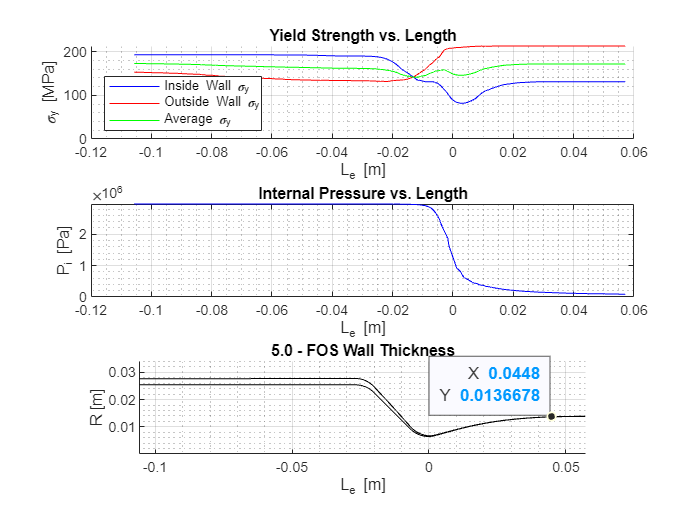

% Save Plot 1 as a PNG file
saveas(wallThicknessPlot,'wallThicknessPlot','png')

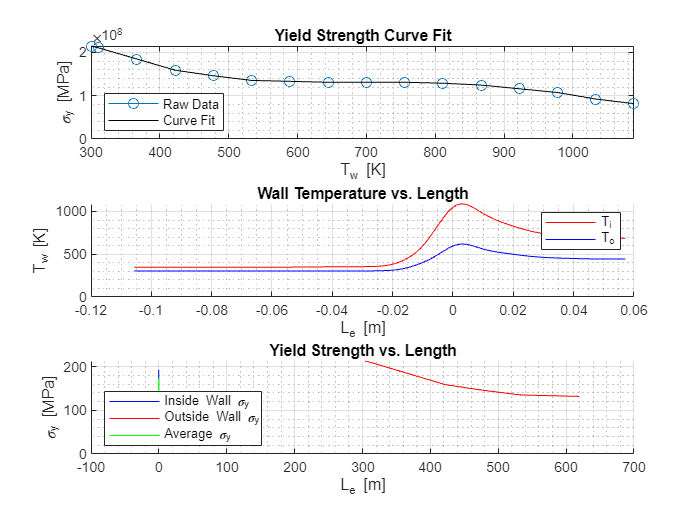

% Save Plot 2 as a PNG file
saveas(yieldStrengthPlot,'yieldStrengthPlot','png')